clear; clc; close all;

%% ---------------- 1. READ PARAMETERS FROM CSV --------------------------
params = readtable("Key_Param_recording.csv", 'ReadRowNames', true);

W_0                = params{"W_0_guess","Value"};
W_e                = params{"W_e","Value"};
W_f                = params{"W_f","Value"};
V_cruise           = params{"V_cruise","Value"};
V_loiter           = params{"V_loiter","Value"};
LD_max             = params{"LD_max","Value"};
LD_cruise          = params{"LD_cruise","Value"};
LD_loiter          = params{"LD_loiter","Value"};
K_LD               = params{"K_LD","Value"};
loiter_alt_ft      = params{"loiter_alt_ft","Value"};
cruise_alt_offset_ft = params{"cruise_alt_offset_ft","Value"};
abs_ceiling_ft     = params{"abs_ceiling_ft","Value"};
M_cruise           = params{"M_cruise","Value"};
Swet_Sref          = params{"Swet_Sref","Value"};
AR                 = params{"AR","Value"};
R_cruise_nmi       = params{"R_cruise_nmi","Value"};
R_alt_km           = params{"R_alt_km","Value"};
Wr_taxi_takeoff    = params{"Wr_taxi_takeoff","Value"};
Wr_climb           = params{"Wr_climb","Value"};
Wr_descent         = params{"Wr_descent","Value"};
Wr_missed_approach = params{"Wr_missed_approach","Value"};
Wr_land_taxi       = params{"Wr_land_taxi","Value"};
L_runway           = params{"L_runway","Value"};
sfc_cruise_mg      = params{"sfc_cruise_mg","Value"};
sfc_loiter_mg      = params{"sfc_loiter_mg","Value"};
E_loiter_min       = params{"E_loiter_min","Value"};
fuel_margin        = params{"fuel_margin","Value"};

%% ---------------- 2. SEGMENT WEIGHT RATIOS (Breguet, as already used) ---
g  = 9.81;                                   % m/s^2 (physical constant)
c_cruise = sfc_cruise_mg*1e-6;               % kg fuel/(N s)
c_loiter = sfc_loiter_mg*1e-6;               % kg fuel/(N s)

R_cruise = R_cruise_nmi*1852;                % m
R_alt    = R_alt_km*1000;                    % m
E_loiter = E_loiter_min*60;                  % s

Wr_cruise = exp(-c_cruise*g*R_cruise/(V_cruise*LD_cruise));  % design cruise
Wr_divert = exp(-c_cruise*g*R_alt   /(V_cruise*LD_cruise));  % diversion cruise
Wr_loiter = exp(-c_loiter*g*E_loiter/LD_loiter);             % holding

%% ---------------- 3. SPLIT TOTAL FUEL W_f ACROSS SEGMENTS ---------------
labels_raw = {'Taxi & Take-off','Climb & Accelerate','Cruise','Descent to Land', ...
              'Missed Approach & Climb','Cruise to alternate destination','Loiter','Land & Taxi-in'};
seg_ratio  = [Wr_taxi_takeoff, Wr_climb, Wr_cruise, Wr_descent, ...
              Wr_missed_approach, Wr_divert, Wr_loiter, Wr_land_taxi];

W_start = W_0;
fuel_kg = zeros(1,numel(seg_ratio));
for i = 1:numel(seg_ratio)
    fuel_kg(i) = W_start*(1 - seg_ratio(i));   % fuel burned in this segment
    W_start    = W_start*seg_ratio(i);         % weight entering next segment
end

Mff          = prod(seg_ratio);                % W_final/W_0 (no margin)
fuel_nominal = W_f*(1 - 0.01);                  % fuel burned, no margin
fuel_reserve_margin = W_f - fuel_nominal;      % remainder = certified margin

labels_raw{end+1} = 'Reserve Margin';
fuel_kg(end+1)     = fuel_reserve_margin;

pct = 100*fuel_kg/W_f;                         % label-only percentage
sum(pct)

ans = 100.0101

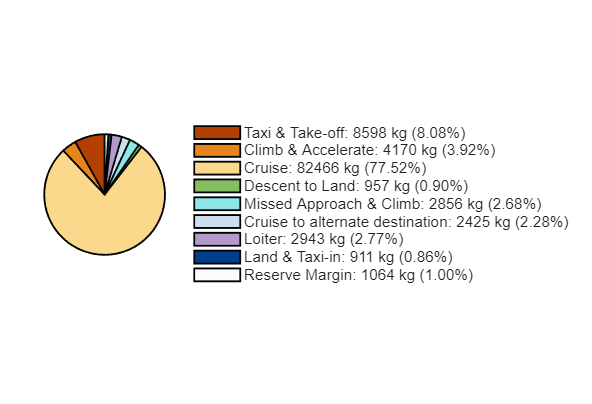

legend_str = cell(size(labels_raw));
for i = 1:numel(labels_raw)
    legend_str{i} = sprintf('%s: %.0f kg (%.2f%%)', labels_raw{i}, fuel_kg(i), pct(i));
end

%% ---------------- 4. COLOUR-BLIND-FRIENDLY PALETTE (Okabe-Ito) ----------
colors = [
          
          0.700 0.250 0.000; % Divert Cruise   - dark brown-orange
          0.900 0.520 0.100; % Missed Approach - orange
          0.980 0.850 0.550; % Descent         - light yellow
          
           0.520 0.745 0.390; % Climb           - light blue
          0.550 0.90 0.90; % Land & Taxi-in  - mid grey
          0.800 0.875 0.945; % Taxi & Take-off  - very light blue
         
          0.700 0.600 0.800; % Loiter          - light purple
          0.000 0.243 0.55; % Cruise          - Imperial blue (dark)
          0.9900 0.9900 0.9900];% Reserve Margin  - black

%% ---------------- 5. PIE CHART -------------------------------------------
figure('Color','w','Position',[100 100 950 650]);
p = pie(fuel_kg);

for i = 1:numel(fuel_kg)
    p(2*i-1).FaceColor = colors(i,:);
    p(2*i-1).EdgeColor = 'k';
    p(2*i-1).LineWidth = 1.2;
    p(2*i).String = '';            % numbers/fractions shown in legend instead
end


legend(legend_str,'Location','eastoutside','FontSize',10,'Box','off');


%% ---------------- 6. CONSOLE SUMMARY -------------------------------------
fprintf('\nFuel breakdown by mission segment (from Key_Param_recording.csv):\n');


Fuel breakdown by mission segment (from Key_Param_recording.csv):


for i = 1:numel(fuel_kg)
    fprintf('  %-18s : %9.1f kg  (%.1f%%)\n', labels_raw{i}, fuel_kg(i), pct(i));
end

  Taxi & Take-off    :    8598.0 kg  (8.1%)
  Climb & Accelerate :    4170.0 kg  (3.9%)
  Cruise             :   82465.6 kg  (77.5%)
  Descent to Land    :     956.8 kg  (0.9%)
  Missed Approach & Climb :    2856.2 kg  (2.7%)
  Cruise to alternate destination :    2425.4 kg  (2.3%)
  Loiter             :    2943.4 kg  (2.8%)
  Land & Taxi-in     :     910.9 kg  (0.9%)
  Reserve Margin     :    1063.8 kg  (1.0%)


fprintf('  %-18s : %9.1f kg\n','TOTAL (W_f)', W_f);

  TOTAL (W_f)        :  106379.4 kg


fprintf('  %-18s : %9.1f kg\n','Sum of slices', sum(fuel_kg));

  Sum of slices      :  106390.2 kg
